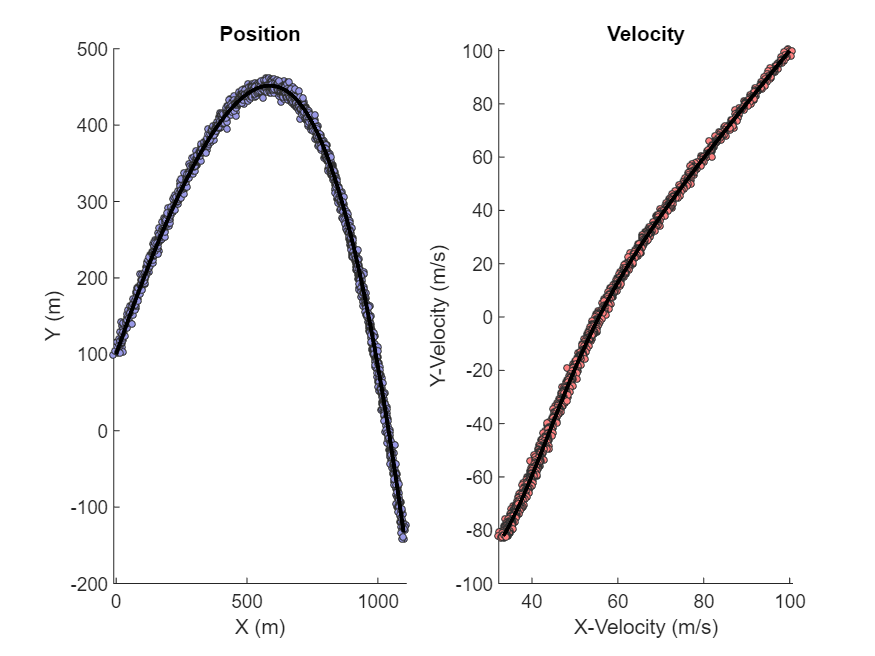

%run a simple model of a falling object in 2D with some inital velocity and
%a drag parameter
dt = 0.01;  %seconds
t_range = 0:dt:20;
x_start = [0, 100, 100, 100];
global m C_D
m=1;
C_D = 0.001;

[T, True_State] = ode45(@rate_func, t_range, x_start);

%generate a noise matrix
pos_noise_sigma = 5;
vel_noise_sigma = 0.5;
Measurement_Noise = diag([pos_noise_sigma pos_noise_sigma vel_noise_sigma vel_noise_sigma]);
%make noisy state by adding random noise to model state
Noisy_State = True_State + randn(size(True_State))*Measurement_Noise;

%plot
figure(1)
clf

% position
subplot(1, 2, 1)
hold on
title("Position")
xlabel("X (m)")
ylabel("Y (m)")
scatter(Noisy_State(:,1), Noisy_State(:,2),10, "filled", "MarkerFaceColor", [0.6 0.6 0.9], "MarkerEdgeColor", [0.2 0.2 0.2]);
plot(True_State(:,1), True_State(:,2), "LineWidth", 2, "Color", "k");
% velocity
subplot(1, 2, 2)
hold on
title("Velocity")
xlabel("X-Velocity (m/s)")
ylabel("Y-Velocity (m/s)")
scatter(Noisy_State(:,3), Noisy_State(:,4),10, "filled", "MarkerFaceColor", [1, 0.5 0.5], "MarkerEdgeColor", [0.2 0.2 0.2]);
plot(True_State(:,3), True_State(:,4), "LineWidth", 2, "Color", "k");

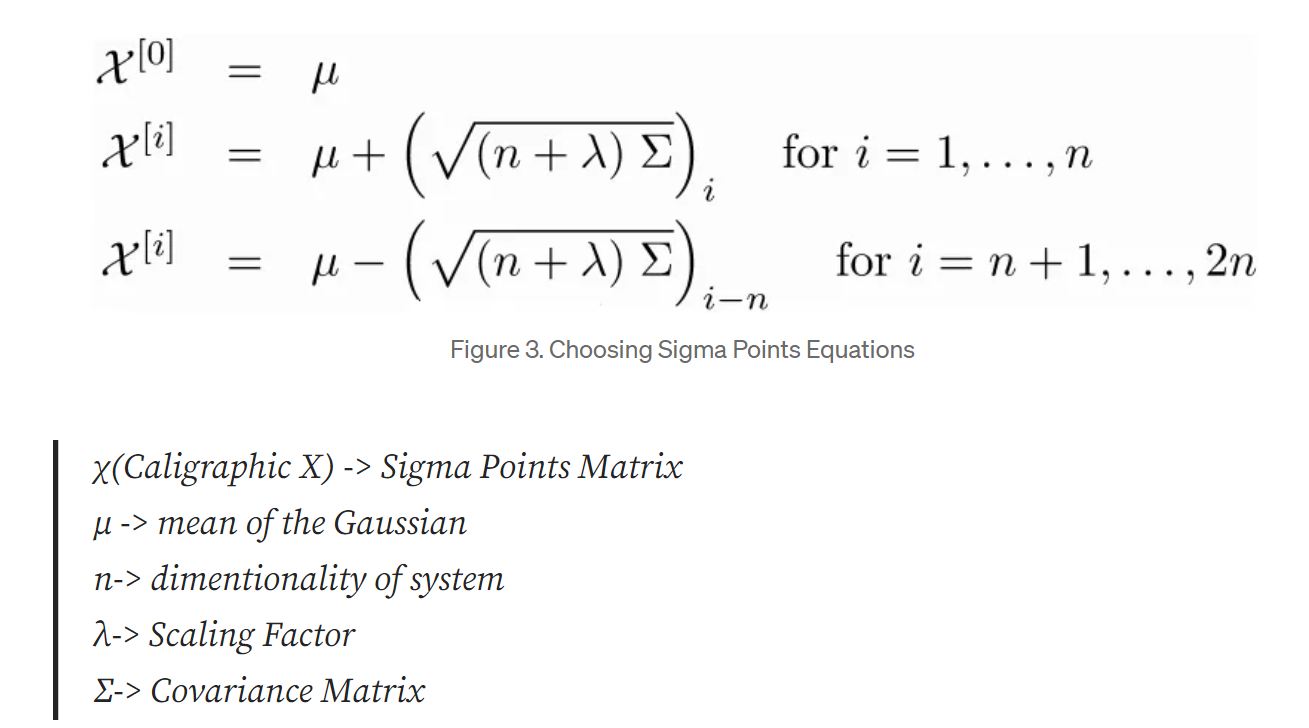

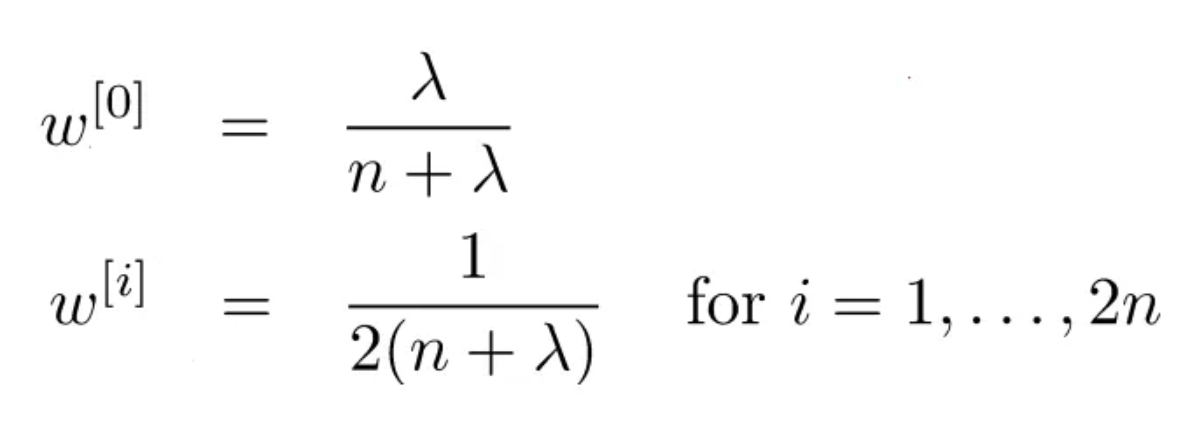

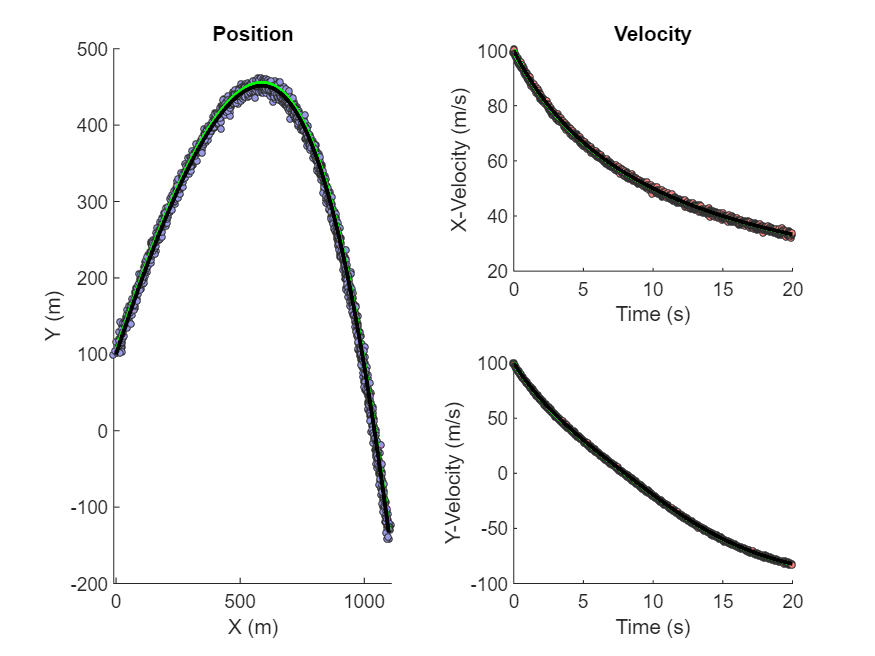

%============Setup==========

N = 4; %this system has N=4 dimensionality (pos and vel in x and y)
lambda = 3*N; %sigma point distance, 3N is a good value according to one study but it can be tuned
current_state = Noisy_State(1,:); %init the state with the first raw noisy measurement
Covariance_Matrix = diag([0.5 0.5 0.2 0.2]); %come up with a dummy State Covariance Matrix to initalize the filter
Process_Noise = diag([0.023 0.023 0.02 0.02]);



%============Loop==========
for t = 1:length(t_range)-1
% for t = 1:2
    cur_time = t_range(t);

    %============Save Stuff For Plotting==========
    state_history(t,:) = current_state;

    
    

    %============calculate sigma points==========

    Sigma_Points = zeros(N, 2*N+1); %init the Sigma Point matrix (2N+1 by N)
    S = (sqrt((N+lambda))*Covariance_Matrix); %can only take square root if Cov = S dot S', then sqrt(cov) = S
    Sigma_Points(:,2*N+1) = current_state; %center point
    for i=1:N
        Sigma_Points(:,i) = current_state + S(i, i); %front points
    end
    for i=N+1:2*N
        Sigma_Points(:,i) = current_state - S(i-N, i-N); %back points
    end

    %===========calculate sigma weights==========

    Sigma_Weights = zeros(2*N+1, 1);  
    Sigma_Weights(2*N+1,:) = lambda/(N+lambda); %center point
    for i = 1:2*N
        Sigma_Weights(i,:) = 1/(2*(N+lambda)); %edge points
    end




    %============Propogate Sigma Points==========
    Sigma_Points_Prime = Sigma_Points;
    



    for i=1:2*N+1

          x_temp = Sigma_Points(1,i);
          y_temp = Sigma_Points(2,i);
          vx_temp = Sigma_Points(3,i);
          vy_temp = Sigma_Points(4,i);

          %linear model of balistic equation
          Sigma_Points_Prime(1,i) = x_temp + (vx_temp * dt);
          Sigma_Points_Prime(2,i) = y_temp + (vy_temp * dt);
          Sigma_Points_Prime(3,i) = vx_temp - (vx_temp^2*C_D/m*sign(vx_temp))*dt;
          Sigma_Points_Prime(4,i) = vy_temp - (vy_temp^2*C_D/m*sign(vy_temp))*dt - 9.8*dt;

    end


    %============Collapse Sigma Points==========
    predicted_state = zeros(N,1);
    predicted_covariance = zeros(N,N);
    predicted_state = (Sigma_Points_Prime * Sigma_Weights); %(1, 2N+1) . (2N+1, N) = (1, N)
    predicted_covariance = ((Sigma_Points_Prime-predicted_state)*(diag(Sigma_Weights)))*((Sigma_Points_Prime-predicted_state)') + Process_Noise;




    %============Predict Measurement==========
    h = eye(N); %we are measuring the state dirrectly so there is no measurment model
    predicted_measurement =  (h*Sigma_Points_Prime)*Sigma_Weights;
    predicted_measurement_covariance = zeros(N,N);
    for i=1:2*N+1
    predicted_measurement_covariance = predicted_measurement_covariance + Sigma_Weights(i) .* ((h*Sigma_Points_Prime(:,i) - predicted_measurement)*(h*Sigma_Points_Prime(:,i) - predicted_measurement)');
    end

    predicted_measurement_covariance = predicted_measurement_covariance + Measurement_Noise;


    measurement = Noisy_State(t,:)';

   %============Kalman Gain========== 
   T = zeros(N,N);
   for i=1:2*N+1
   T = T + Sigma_Weights(i).*((Sigma_Points_Prime(:,i)-predicted_state)*(Sigma_Points_Prime(:,i)-predicted_measurement)');
 
   end

   Kalman_Gain = T/predicted_measurement_covariance;


   %============Update State==========
   current_state = predicted_state + Kalman_Gain*(measurement - predicted_measurement);
   Covariance_Matrix = (eye(N) - Kalman_Gain*T).*predicted_covariance;  %element-wise matrix multiplication!!

 


  



end
%plot
figure(1)
clf
t = tiledlayout('flow');



% position
nexttile([2 1]);
hold on
title("Position")
xlabel("X (m)")
ylabel("Y (m)")
scatter(Noisy_State(:,1), Noisy_State(:,2),10, "filled", "MarkerFaceColor", [0.6 0.6 0.9], "MarkerEdgeColor", [0.2 0.2 0.2]);
plot(state_history(:,1), state_history(:,2), "LineWidth", 2, "Color", "g");
plot(True_State(:,1), True_State(:,2), "LineWidth", 2, "Color", "k");
% velocity
nexttile([1 1]);
hold on
title("Velocity")
xlabel("Time (s)")
ylabel("X-Velocity (m/s)")
scatter(t_range, Noisy_State(:,3), 10, "filled", "MarkerFaceColor", [1, 0.5 0.5], "MarkerEdgeColor", [0.2 0.2 0.2]);
plot(t_range(2:end), state_history(:,3),  "LineWidth", 2, "Color", "g");
plot(t_range, True_State(:,3), "LineWidth", 2, "Color", "k");

nexttile([1 1]);
hold on

xlabel("Time (s)")
ylabel("Y-Velocity (m/s)")
scatter(t_range, Noisy_State(:,4), 10, "filled", "MarkerFaceColor", [1, 0.5 0.5], "MarkerEdgeColor", [0.2 0.2 0.2]);
plot(t_range(2:end), state_history(:,4),  "LineWidth", 2, "Color", "g");
plot(t_range, True_State(:,4), "LineWidth", 2, "Color", "k");

function rate = rate_func(~, X)
%a = F/m
global m C_D

x_pos = X(1);
y_pos = X(2);
x_vel = X(3);
y_vel = X(4);

%calculate forces
f_drag_x = C_D * x_vel^2 * sign(x_vel) * -1;
f_drag_y = C_D * y_vel^2 * sign(y_vel) * -1;
f_grav_y = -9.8*m;

%calculate derivatives
dxdt = x_vel;
dydt = y_vel;
dvxdt = (f_drag_x) / m;
dvydt = (f_drag_y + f_grav_y) / m;

%construct rate vector
rate = [dxdt ; dydt ; dvxdt ; dvydt];

end